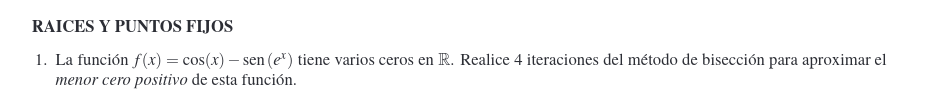

clear
syms g(x)
g(x) = cos(x)-sin(exp(x))

$$g(x) = \cos\left(x\right)-\sin\left({\mathrm{e}}^{x}\right)$$

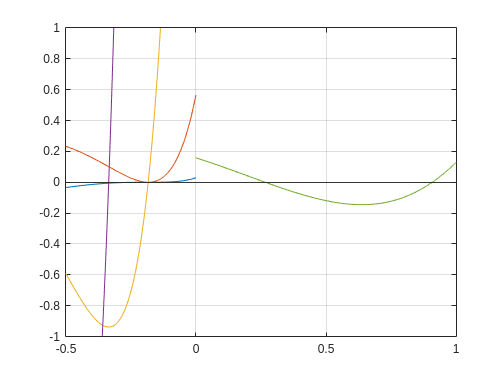



fplot(g(x),[0 1])
grid on
yline(0)


f = matlabFunction(g(x))

f = function_handle with value:
    @(x)-sin(exp(x))+cos(x)



a = 0.2625

a = 0.2625

b = 0.275

b = 0.2750

medio = ((a+b)/2 )

medio = 0.2688

c = feval(f,medio)

c = -0.0016

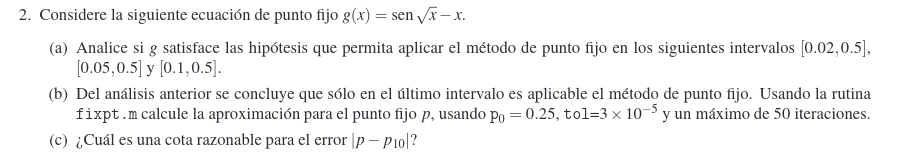

clear
clf

syms f(x)
f(x) = sin(sqrt(x)-x)

$$f(x) = -\sin\left(x-\sqrt{x}\right)$$

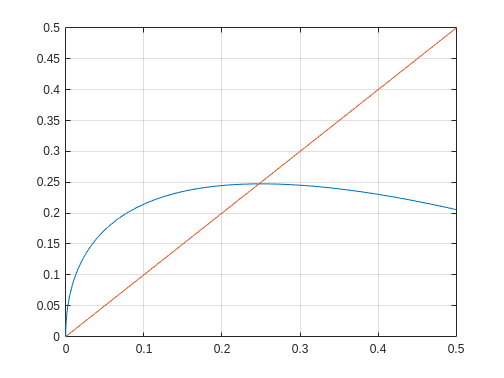


fplot(f(x),[0 0.5])
hold on
grid on
fplot(x,[0 0.5])

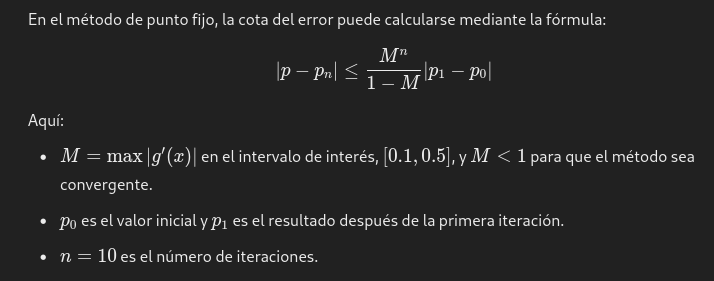

% C)

df(x) = diff(f(x))

$$df(x) = \cos\left(x-\sqrt{x}\right)\,\left(\frac{1}{2\,\sqrt{x}}-1\right)$$

df = matlabFunction(df(x))

df = function_handle with value:
    @(x)cos(x-sqrt(x)).*(1.0./sqrt(x)./2.0-1.0)



M = max(feval(df,linspace(0.2,0.4,1000)))

M = 0.1144


vpa((M^10/(1 - M)) * (f(0.4)-f(0.2)))

$$ans = -0.0000000000062400225633884517290820908251102$$

clear
clf

syms f(x)

f(x) = (cos(exp(x)-2)) - (exp(x)/4) +2

$$f(x) = \cos\left({\mathrm{e}}^{x}-2\right)-\frac{{\mathrm{e}}^{x}}{4}+2$$

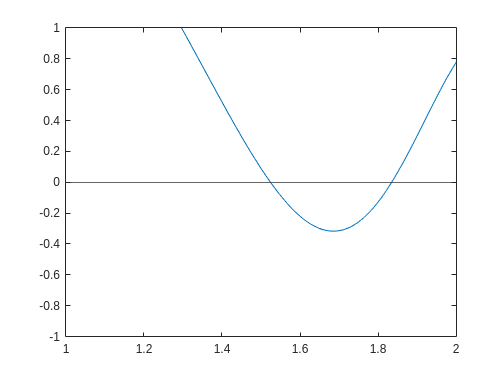

fplot(f(x), [1 2])
ylim([-1 1])
yline(0)


f = matlabFunction(f(x))

f = function_handle with value:
    @(x)cos(exp(x)-2.0)-exp(x)./4.0+2.0



[c, err, yc] = bisect (f, 1.4, 1.6, 1e-6)

c = 1.5241

err = 7.6294e-07

yc = 3.4001e-07

syms f(x)

f(x) = (exp(x) * cos(3*x)) - sin(5*x+1)

$$f(x) = \cos\left(3\,x\right)\,{\mathrm{e}}^{x}-\sin\left(5\,x+1\right)$$


df(x) = diff(f(x))

$$df(x) = \cos\left(3\,x\right)\,{\mathrm{e}}^{x}-5\,\cos\left(5\,x+1\right)-3\,\sin\left(3\,x\right)\,{\mathrm{e}}^{x}$$

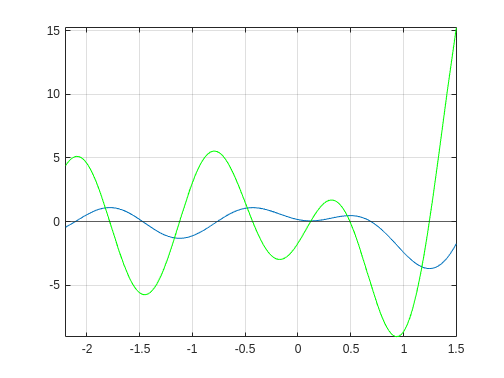


fplot(f(x),[-2.2 1.5])
grid on
hold on
yline(0)
fplot(df(x),[-2.2 1.5],'g')


[M, err, yc] = bisect (df, 1, 1.5, 1e-6);
minimo = M

minimo = 1.2449

vpa(minimo,16)

$$ans = 1.244904041290283$$


[Ma1, err, yc] = bisect (df, -2, -1.5, 1e-6);
max1 = Ma1;
max1 = feval(f,max1);
vpa(max1,16)

$$ans = 1.098089613703952$$


[Ma2, err, yc] = bisect (df, -0.5, 0, 1e-6);

max2 = Ma2;
max2 = feval(f,max2);
vpa(max2,16)

$$ans = 1.093037665694966$$


maximo = max1

$$maximo = \sin\left(\frac{16599253}{2097152}\right)+\cos\left(\frac{11217843}{2097152}\right)\,{\mathrm{e}}^{-\frac{3739281}{2097152}}$$


fprintf('El mínimo es: %f y el máximo es: %f\n', minimo, max1);

El mínimo es: 1.244904 y el máximo es: 1.098090


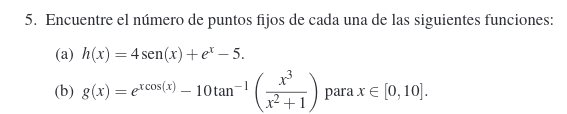

clear
clf
syms h(x)
h(x) = 4*sin(x) + exp(x) - 5

$$h(x) = {\mathrm{e}}^{x}+4\,\sin\left(x\right)-5$$

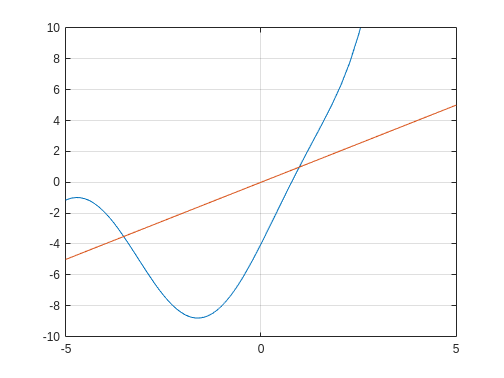


fplot(h)
hold on
grid on
fplot(x)
ylim([-10 10])

fprintf('El numero de pintos fijos es: %f', 2);

El numero de pintos fijos es: 2.000000

clear
clf
syms g(x)
g(x) = exp(x*cos(x))-(10*atan(x^3/(x^2+1)))

$$g(x) = {\mathrm{e}}^{x\,\cos\left(x\right)}-10\,\mathrm{atan}\left(\frac{x^{3}}{x^{2}+1}\right)$$

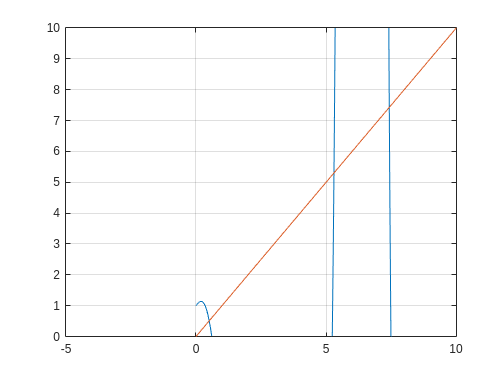


fplot(g, [0 10])
hold on
grid on
fplot(x)
ylim([0 10])

fprintf('El numero de pintos fijos es: %f', 3);

El numero de pintos fijos es: 3.000000

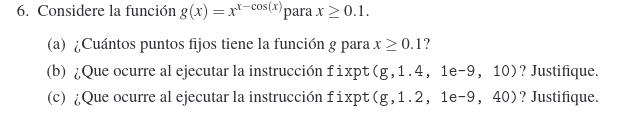

clear
clf

syms g(x)

g(x) = x^(x - cos(x))

$$g(x) = x^{x-\cos\left(x\right)}$$

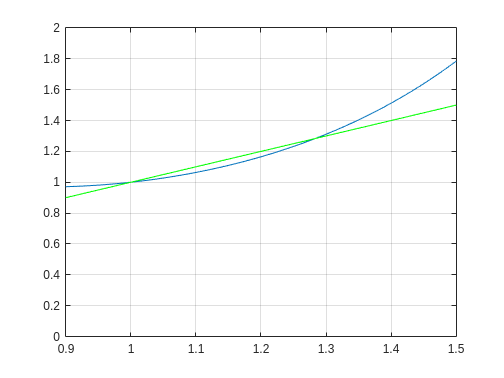

fplot(g,[0.9 1.5])
hold on 
grid on
fplot(x, [0.9 1.5],'g')
ylim([0 2])


fixpt(g,1.4, 1e-9, 10)

err = 0.1127

err = 0.3131

err = 1.6679

err = 252.3767

err = Inf

err = NaN

err = NaN

err = NaN

err = NaN

err = NaN

maximum number of iterations exceeded


ans = NaN

fprintf("El numero de interaciones se ha excedido y no converge, por no ser contractiva")

El numero de interaciones se ha excedido y no converge, por no ser contractiva


fixpt(g,1.2, 1e-9, 40)

err = 0.0350

err = 0.0402

err = 0.0398

err = 0.0333

err = 0.0233

err = 0.0140

err = 0.0075

err = 0.0037

err = 0.0018

err = 8.2675e-04

err = 3.8325e-04

err = 1.7686e-04

err = 8.1448e-05

err = 3.7472e-05

err = 1.7232e-05

err = 7.9231e-06

err = 3.6425e-06

err = 1.6745e-06

err = 7.6979e-07

err = 3.5387e-07

err = 1.6267e-07

err = 7.4781e-08

err = 3.4377e-08

err = 1.5803e-08

err = 7.2646e-09

err = 3.3395e-09

err = 1.5352e-09

err = 7.0571e-10

ans = 1.0000

fprintf("Converge corretamente el valor x = 1")

Converge corretamente el valor x = 1

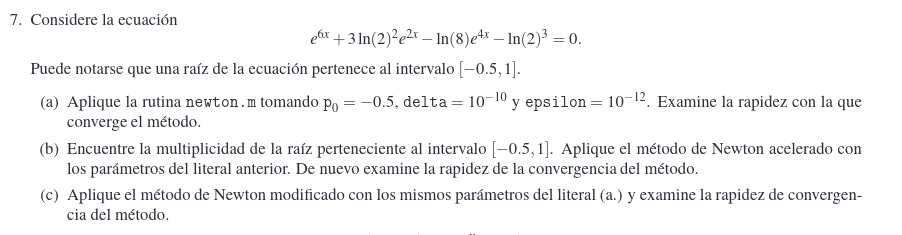

clear
clf


syms f(x)

f(x) = exp(6*x) + (3*log(2)^2 * exp(2*x)) - (log(8)*exp(4*x)) - (log(2)^3)

$$f(x) = \frac{3245652021676565\,{\mathrm{e}}^{2\,x}}{2251799813685248}-\frac{4682486076124019\,{\mathrm{e}}^{4\,x}}{2251799813685248}+{\mathrm{e}}^{6\,x}-\frac{5999238794410127}{18014398509481984}$$

df(x) = diff(f(x))

$$df(x) = \frac{3245652021676565\,{\mathrm{e}}^{2\,x}}{1125899906842624}-\frac{4682486076124019\,{\mathrm{e}}^{4\,x}}{562949953421312}+6\,{\mathrm{e}}^{6\,x}$$


f = matlabFunction(f(x))

f = function_handle with value:
    @(x)exp(x.*2.0).*1.441359041754604-exp(x.*4.0).*2.079441541679836+exp(x.*6.0)-3.330246519889294e-1


df = matlabFunction(df(x))

df = function_handle with value:
    @(x)exp(x.*2.0).*2.882718083509208-exp(x.*4.0).*8.317766166719343+exp(x.*6.0).*6.0


df2 = matlabFunction(diff(df(x)))

df2 = function_handle with value:
    @(x)exp(x.*2.0).*5.765436167018416-exp(x.*4.0).*3.327106466687737e+1+exp(x.*6.0).*3.6e+1


df3 = matlabFunction(diff(df2(x)))

df3 = function_handle with value:
    @(x)exp(x.*2.0).*1.153087233403683e+1-exp(x.*4.0).*1.330842586675095e+2+exp(x.*6.0).*2.16e+2



[p0, err, k, y] = newton (f, df, -0.5, 10e-10, 10e-12, 100)

p0 = -0.1834

err = 6.6806e-05

k = 18

y = -6.3464e-12



fplot(f, [-0.5 0])
hold on
fplot(df,[-0.5 0])
yline(0)
ylim([-1 1])
fprintf("Como la multiplicidad es diferente de 1 converge linealmente")

Como la multiplicidad es diferente de 1 converge linealmente

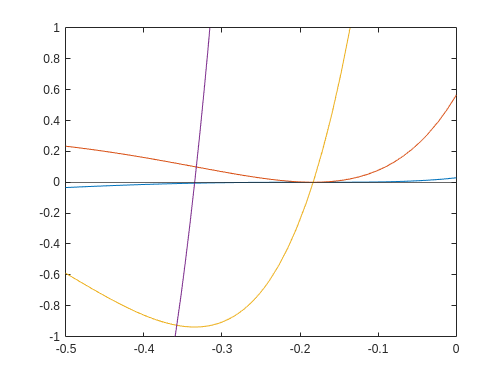

fplot(df2, [-0.5 0])
fplot(df3, [-0.5 0])

fprintf("Como la tercera derivada evaluada en f(x) = 0 no es 0 por lo tanto sumultiplicidad es 3")

Como la tercera derivada evaluada en f(x) = 0 no es 0 por lo tanto sumultiplicidad es 3

## Newton modificado

[p0, err, k, y] = newtonMod (f, df, df2 ,-0.5, 10e-10, 10e-12, 100)

p0 = -0.1833

err = 0.0063

k = 3

y = -1.7908e-13


fprintf("Con newton modificado convergio con 3 operaciones mientras que con el normal necesito" + ...
    " 18")

Con newton modificado convergio con 3 operaciones mientras que con el normal necesito18